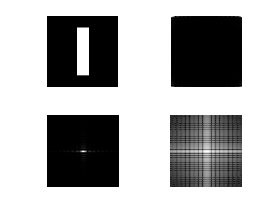

% Punto 1
figure
[I] = imresize(imread("Fig0419.tif"),[100 100]);
subplot(2,2,1),imshow(I,[])

a = abs(fft2(I));
subplot(2,2,2),imshow(a, [])

b = abs(fftshift(a));
subplot(2,2,3),imshow(b, [])

c = log(1 + fftshift(a));
subplot(2,2,4),imshow(c,[])

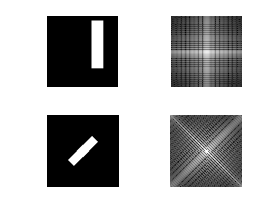

% Punto 2
figure
I2 = imtranslate(I,[20 -10]);
subplot(2,2,1),imshow(I2)

a2 = log(1 + fftshift(abs(fft2(I2))));
subplot(2,2,2),imshow(a2, [])

I3 = imrotate(I,-45,"bicubic");
subplot(2,2,3),imshow(I3)

b2 = log(1 + fftshift(abs(fft2(I3))));
subplot(2,2,4),imshow(b2, [])

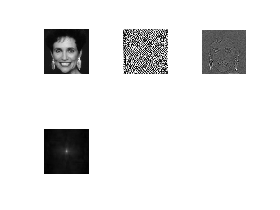

% Punto 3
figure
I4 = imresize(imread("FigP0402(a)(woman).tif"),[100 100]);
subplot(2,3,1),imshow(I4)

%spectrum
I5S= log(1 + fftshift(abs(fft2(I4))));
% subplot(2,3,4),imshow(a3_3,[])

a3 = fft2(I4);
% phase angle
a3_1 = exp(1i*angle(a3));
subplot(2,3,2),imshow(real(a3_1), [])
% phase angle reconstrution
a3_2 = ifft2(a3_1);
subplot(2,3,3),imshow(real(a3_2),[])
% reconstruction using only spectrum
a3_3 = ifftshift(ifft2(abs(a3)));
subplot(2,3,4),imshow(a3_3,[])


% phase angle woman - rectangle spectrum
% a3_4 = a3_1.*c;
% a3_4 = real(ifft2(ifftshift(a3_4)));
% subplot(2,3,5),imshow(a3_4,[])

% phase angle rectangle - woman spectrum
% a3_5 = exp(1i*angle(fft2(I))).*I5S;
% a3_5 = real(ifft2(ifftshift(a3_5)));
% subplot(2,3,6),imshow(a3_5,[])

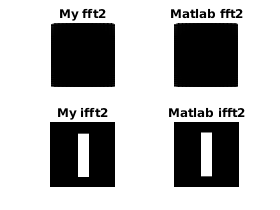

% Punto 4
figure
subplot(2,2,1),imshow(abs(myfft2(I)),[]), title("My fft2")
subplot(2,2,2),imshow(abs(fft2(I)),[]), title("Matlab fft2")
subplot(2,2,3),imshow(myifft2(fft2(I)),[]), title("My ifft2")
subplot(2,2,4),imshow((ifft2(fft2(I))),[]), title("Matlab ifft2")

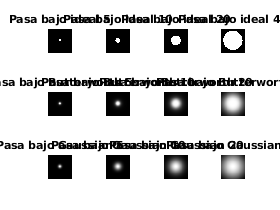

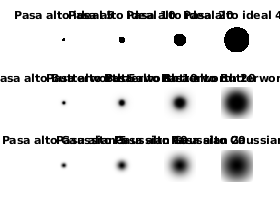

% Punto 5 - 6

cortes = [5,10,20,40];
filtros = ["ideal","Butterworth","Gaussian"];
pasa = ["bajo","alto"];

for p=1:2
    figure;
    for j=1:3
        for i=1:4
            subplot(3,4,i+4*(j-1)), imshow(fourierFilters([100 100],filtros(j),pasa(p),cortes(i)),[]),title(strcat("Pasa ",pasa(p)," ",filtros(j)," ",int2str(cortes(i))),"FontSize",8)
        end
    end
end

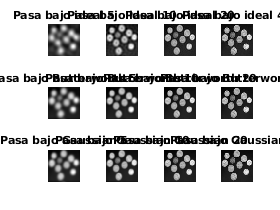

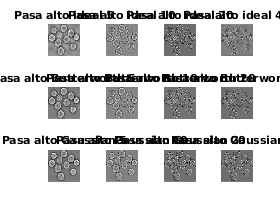

% Punto 5 - 6

I5 = imresize(imread("coins.jpg"),[100 100]); 

for p=1:2
    figure;
    for j=1:3
        for i=1:4
            mask = fourierFilters(size(I5),filtros(j),pasa(p),cortes(i));
            I5F = fft2(I5);
            I5FS = fftshift(I5F);
            
            fmask = mask.*I5FS;
            
            Ifiltered = real(ifft2(ifftshift(fmask)));
    
            subplot(3,4,i+4*(j-1)), imshow(Ifiltered,[]),title(strcat("Pasa ", pasa(p)," ",filtros(j)," ",int2str(cortes(i))),"FontSize",8)
        end
    end
end

function [filtro] = fourierFilters(tamano,tipo,pasa,frecuencia)

    n = 2;
    filtro = zeros(tamano(1),tamano(2));
    domain = @(y,x) ((y-floor(tamano(1)/2))^2 + (x-floor(tamano(2)/2))^2)^0.5;

    switch tipo
        case 'ideal'
            filter = @(y,x) domain(y,x)<=frecuencia;
        case 'Butterworth'
            filter = @(y,x) 1/(1 + (domain(y,x)/frecuencia)^(2*n));
        case 'Gaussian'
            filter = @(y,x) exp((-1/(2*(frecuencia^2)))*((domain(y,x))^2));
    end

    for y=1:tamano(1)
        for x=1:tamano(2)
            filtro(y,x) = filter(y,x);
            if pasa == "alto"
                filtro(y,x) = 1 - filtro(y,x);
            end
        end
    end 
end

-

function [fft2] = myfft2(imagen)

    [N, M] = size(imagen);
    fft2=zeros(N,M);

    for u=1:M
        for v=1:N
            sum_x=0;
            for x=1:M
                sum_y=0;
                for y=1:N
                    sum_y=sum_y+complex(double(imagen(y,x)))*exp(-2i*pi*((u-1)*(x-1)/M + (v-1)*(y-1)/N));
                end
                sum_x=sum_x+sum_y;
            end
            fft2(v,u)=sum_x;
        end
    end
end

-

function [ifft2] = myifft2(imagen)

[N, M] = size(imagen);
ifft2=zeros(N,M);

for x=1:M
    for y=1:N
        sum_u=0;
        for u=1:M
            sum_v=0;
            for v=1:N
                sum_v=sum_v + complex(double(imagen(v,u)))*exp(-2i*pi*((u-1)*(x-1)/M + (v-1)*(y-1)/N));
            end
            sum_u=sum_u+sum_v;
        end
        ifft2(y,x)=real(sum_u)/(M*N);
    end
end
end